# Surfaces defined by parametric functions

Finally, a more general representation of a surface involves expressing its coordinates in terms of two independent variables


$$x = f(u,v), y = g(u,v), z = h(u,v)$$


where u and v take values in some domain in 2D. For example, if we restrict $u \in [a,b]$ and $v \in [c,d]$ then the domain in the uv-plane is a rectangle. At each point in this rectangle, we determine the coordinates (x,y,z), and if we glue all of these points together then we define a parametric surface in the xyz-space. For example,


$$x = \sin u \cos v, y = \sin u \sin v, z = \cos u, u \in [0,\pi], v \in [0,2\pi]$$


defines a sphere of radius 1, centered at the origin. In order to visualize this in Matlab we first define a mesh grid in the uv-domain

u = linspace(0,pi,100)

u =          0    0.0317    0.0635    0.0952    0.1269    0.1587    0.1904    0.2221    0.2539    0.2856    0.3173    0.3491    0.3808    0.4125    0.4443    0.4760    0.5077    0.5395    0.5712    0.6029    0.6347    0.6664    0.6981    0.7299    0.7616    0.7933    0.8251    0.8568    0.8885    0.9203


v = linspace(0,2*pi,100)

v =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405


[U,V] = meshgrid(u,v)

U =          0    0.0317    0.0635    0.0952    0.1269    0.1587    0.1904    0.2221    0.2539    0.2856    0.3173    0.3491    0.3808    0.4125    0.4443    0.4760    0.5077    0.5395    0.5712    0.6029    0.6347    0.6664    0.6981    0.7299    0.7616    0.7933    0.8251    0.8568    0.8885    0.9203
         0    0.0317    0.0635    0.0952    0.1269    0.1587    0.1904    0.2221    0.2539    0.2856    0.3173    0.3491    0.3808    0.4125    0.4443    0.4760    0.5077    0.5395    0.5712    0.6029    0.6347    0.6664    0.6981    0.7299    0.7616    0.7933    0.8251    0.8568    0.8885    0.9203
         0    0.0317    0.0635    0.0952    0.1269    0.1587    0.1904    0.2221    0.2539    0.2856    0.3173    0.3491    0.3808    0.4125    0.4443    0.4760    0.5077    0.5395    0.5712    0.6029    0.6347    0.6664    0.6981    0.7299    0.7616    0.7933    0.8251    0.8568    0.8885    0.9203
         0    0.0317    0.0635    0.0952    0.1269    0.1587    0.1904    0.2221    0.2539   

V =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635
    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269    0.1269
    0.1904    0.1904    0.1904    0.1904    0.1904    0.1904    0.1904    0.1904    0.1904   

Now we define a function that defines the parametric equations for the sphere. You will find it at the end of this script, but we copy it here for clarity

**function [x,y,z] = sphereparam(u,v)**

**    x = sin(u) cos(v)**

**    y = sin(u) sin(v)**

**    z = cos(u)**

**end**

Now we can call the function, and then use **surf** to visualize the sphere.

[X,Y,Z] = sphereparam(U,V)

X =          0    0.0317    0.0634    0.0951    0.1266    0.1580    0.1893    0.2203    0.2511    0.2817    0.3120    0.3420    0.3717    0.4009    0.4298    0.4582    0.4862    0.5137    0.5406    0.5671    0.5929    0.6182    0.6428    0.6668    0.6901    0.7127    0.7346    0.7557    0.7761    0.7958
         0    0.0317    0.0633    0.0949    0.1263    0.1577    0.1889    0.2199    0.2506    0.2812    0.3114    0.3413    0.3709    0.4001    0.4289    0.4573    0.4852    0.5126    0.5396    0.5659    0.5917    0.6169    0.6415    0.6654    0.6887    0.7113    0.7331    0.7542    0.7746    0.7942
         0    0.0315    0.0629    0.0943    0.1256    0.1567    0.1877    0.2185    0.2491    0.2795    0.3095    0.3393    0.3687    0.3977    0.4263    0.4545    0.4823    0.5095    0.5363    0.5625    0.5881    0.6132    0.6376    0.6614    0.6845    0.7070    0.7287    0.7497    0.7699    0.7894
         0    0.0312    0.0623    0.0933    0.1243    0.1551    0.1858    0.2163    0.2466   

Y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0159    0.0179    0.0198    0.0217    0.0236    0.0254    0.0273    0.0291    0.0308    0.0326    0.0343    0.0360    0.0376    0.0392    0.0408    0.0423    0.0438    0.0452    0.0466    0.0479    0.0492    0.0505
         0    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0279    0.0318    0.0357    0.0395    0.0433    0.0470    0.0508    0.0544    0.0580    0.0615    0.0650    0.0684    0.0718    0.0751    0.0783    0.0814    0.0844    0.0874    0.0902    0.0930    0.0957    0.0983    0.1007
         0    0.0060    0.0120    0.0180    0.0240    0.0299    0.0358    0.0417    0.0475   

Z =     1.0000    0.9995    0.9980    0.9955    0.9920    0.9874    0.9819    0.9754    0.9679    0.9595    0.9501    0.9397    0.9284    0.9161    0.9029    0.8888    0.8738    0.8580    0.8413    0.8237    0.8053    0.7861    0.7660    0.7453    0.7237    0.7015    0.6785    0.6549    0.6306    0.6056
    1.0000    0.9995    0.9980    0.9955    0.9920    0.9874    0.9819    0.9754    0.9679    0.9595    0.9501    0.9397    0.9284    0.9161    0.9029    0.8888    0.8738    0.8580    0.8413    0.8237    0.8053    0.7861    0.7660    0.7453    0.7237    0.7015    0.6785    0.6549    0.6306    0.6056
    1.0000    0.9995    0.9980    0.9955    0.9920    0.9874    0.9819    0.9754    0.9679    0.9595    0.9501    0.9397    0.9284    0.9161    0.9029    0.8888    0.8738    0.8580    0.8413    0.8237    0.8053    0.7861    0.7660    0.7453    0.7237    0.7015    0.6785    0.6549    0.6306    0.6056
    1.0000    0.9995    0.9980    0.9955    0.9920    0.9874    0.9819    0.9754    0.9679   

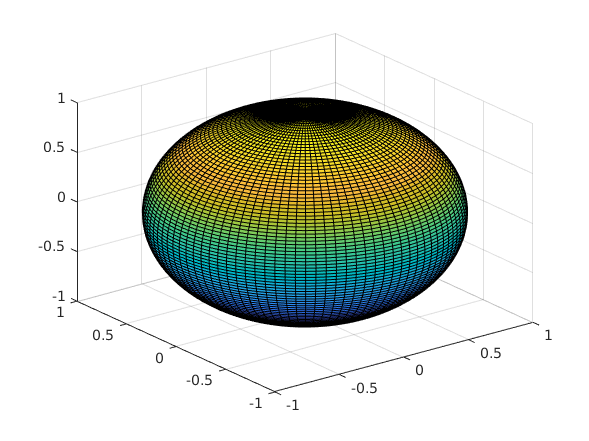

surf(X,Y,Z)

**Exercise 1: **Consider the following parametric equations


$$x = (a + r \cos u) \cos v, y = (a+r\cos u) \sin v, z = r \sin u
$$


with r < a, and defined on the domain $u \in [0, 2\pi], v \in [0, 2\pi] $.

- Write a function that accepts u,v,a, and r as inputs, and returns x,y, and z.

- Visualize the surface for some different values of a and r.

- What features of the surface do the parameters r and a control?

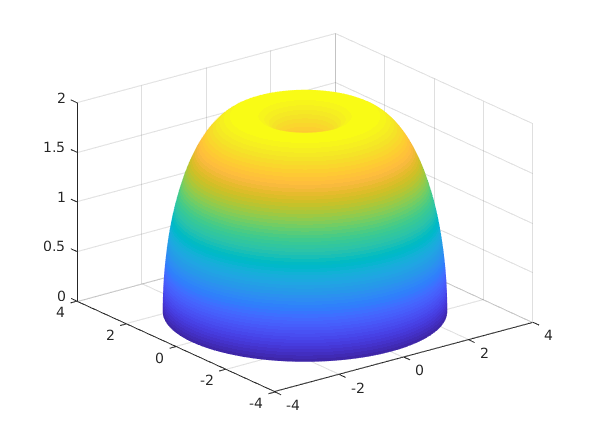

a = 1.5;
r = 2;
[X,Y,Z] = myfunc1(U,V,a,r);
surf(X,Y,Z)
shading('interp')

function [x,y,z] = sphereparam(u,v)
    x = sin(u).*cos(v);
    y = sin(u).*sin(v);
    z = cos(u);
end

function [x,y,z] = myfunc1(u,v,a,r)
    term = a + r * cos(u);
    x = term .* cos(v);
    y = term .* sin(v);
    z = r * sin(u);
end